# PIPPET simulations for manuscript

## Phase response for fixed C

Expecting four evenly spaced events, equally. Plots are based on the assumption that each event is reached with identical phase uncertainty.

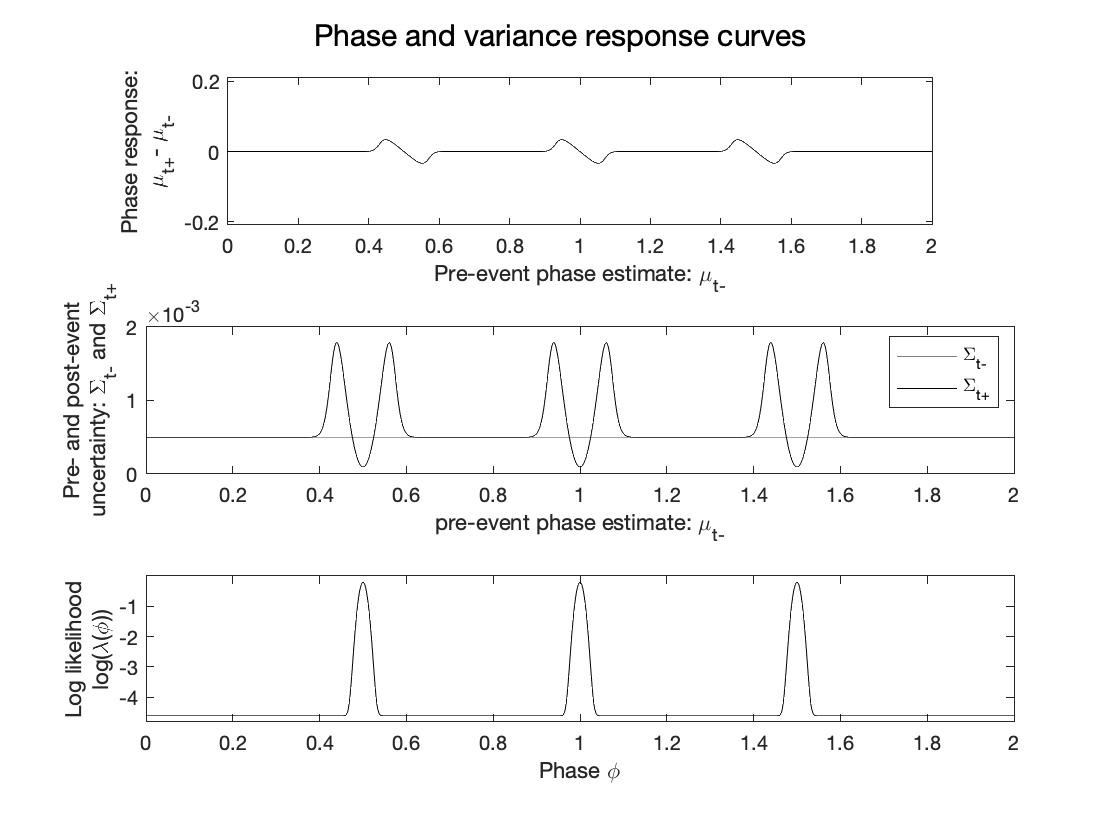

params = PIPPET_params(...
    'events_unit', [.5],...
    'expected_period', .5,...
    'variance_unit', [.0001],...
    'lambda_unit', [.02],...
    'expected_cycles', 3,...
    'event_times', []);

% lambda_0 = .00000001;
x_list = 0:.002:2;

C = .0005;

mu_list = zeros(size(x_list));
C_list = zeros(size(x_list));
for i = 1:length(x_list)
    mu_list(i) = params.streams{1}.mu_bar(x_list(i), C);
    C_list(i) = params.streams{1}.C_bar(x_list(i), C);
end

PRC = mu_list - x_list;

figure()
subplot(3,1,1)
plot(x_list, PRC, 'k')
xlim([min(x_list), max(x_list)])
%axis equal
ylabel({'Phase response:';'\mu_{t+}- \mu_{t-}'})
xlabel({'Pre-event phase estimate: \mu_{t-}'})
axis('equal')
%set(get(gca, "YLabel"), 'Rotation', 0)

subplot(3,1,2)
plot(x_list, zeros(size(x_list))+C, 'color', [.5,.5,.5])
hold on

plot(x_list, C_list, 'k')
ylabel({'Pre- and post-event';'uncertainty: \Sigma_{t-} and \Sigma_{t+}'})
xlabel({'Pre-event phase estimate: \mu_{t-}'})
legend('\Sigma_{t-}','\Sigma_{t+}')
%set(get(gca, "YLabel"), 'Rotation', 0)

subplot(3,1,3)
plot(x_list, log(params.streams{1}.expect_func(x_list)), 'k')
ylabel({'Log likelihood';'log(\lambda(\phi))'})
xlabel('Phase \phi')
ylim([min(log(params.streams{1}.expect_func(x_list)))-.2, max(log(params.streams{1}.expect_func(x_list)))+.2])
%set(get(gca, "YLabel"), 'Rotation', 0)

sgtitle('Phase and variance response curves')

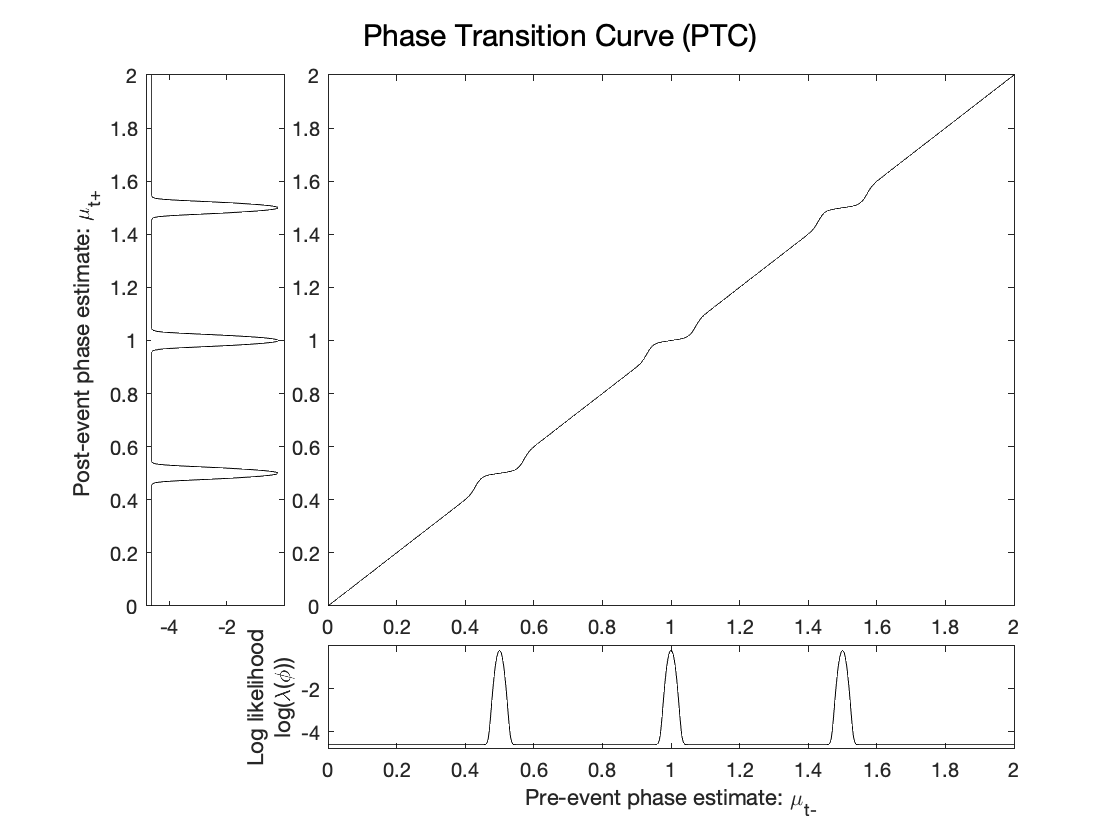


figure()

subplot(5,5, [2,3,4,5, 7,8,9,10, 12,13,14,15, 17,18,19,20])
plot(x_list, mu_list, 'k')
xlim([min(x_list), max(x_list)])
ylim([min(x_list), max(x_list)])

subplot(5,5, [1,6,11,16])
plot(log(params.streams{1}.expect_func(x_list)), x_list, 'k')
ylabel('Post-event phase estimate: \mu_{t+} ')
xlim([min(log(params.streams{1}.expect_func(x_list)))-.2, max(log(params.streams{1}.expect_func(x_list)))+.2])


subplot(5,5, [22,23,24,25])
plot(x_list, log(params.streams{1}.expect_func(x_list)), 'k')
xlabel('Pre-event phase estimate: \mu_{t-}')
ylim([min(log(params.streams{1}.expect_func(x_list)))-.2, max(log(params.streams{1}.expect_func(x_list)))+.2])
ylabel({'Log likelihood';'log(\lambda(\phi))'})

sgtitle('Phase Transition Curve (PTC)')

## Time warping

What happens with strong expectations when nothing happens, as compared to when expectations are met? Time dilation!

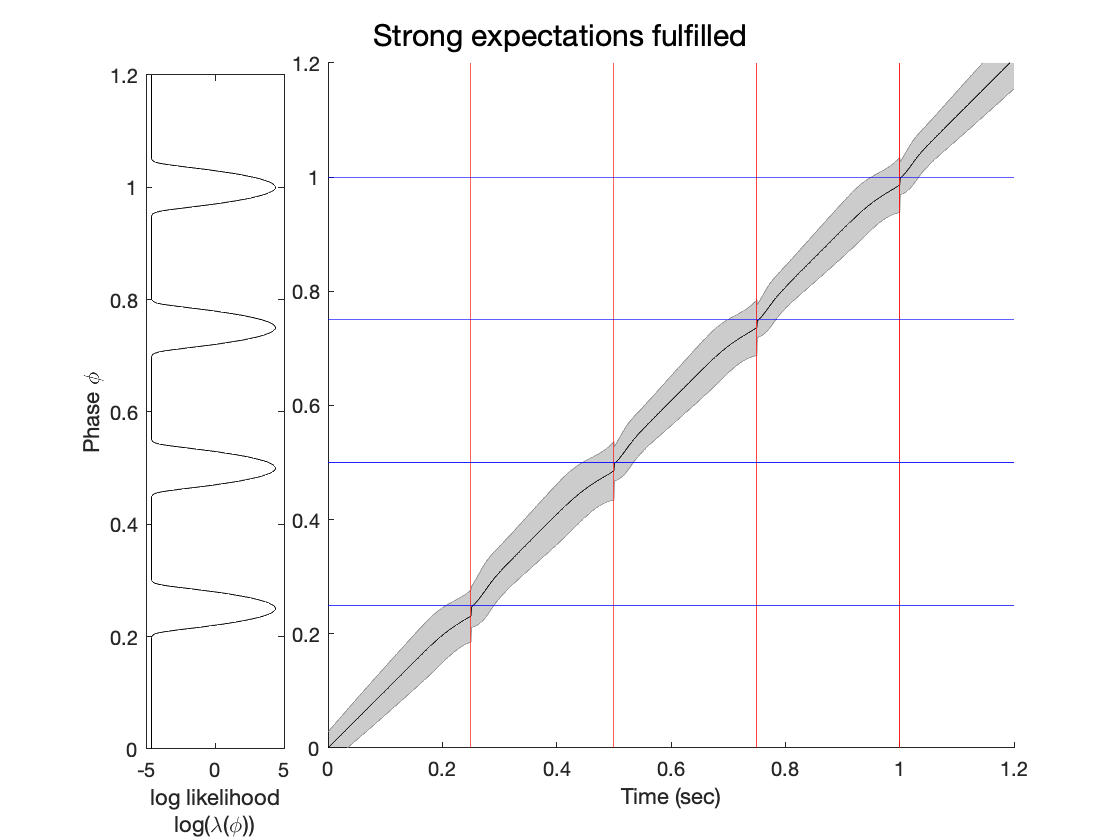



params = PIPPET_params(...
    'lambda_unit', 100*0.02,...
    'event_times',[.25, .5,.75, 1],...
    'title', 'Strong expectations fulfilled');
[mu_list, C_list] = run_PIPPET(params);

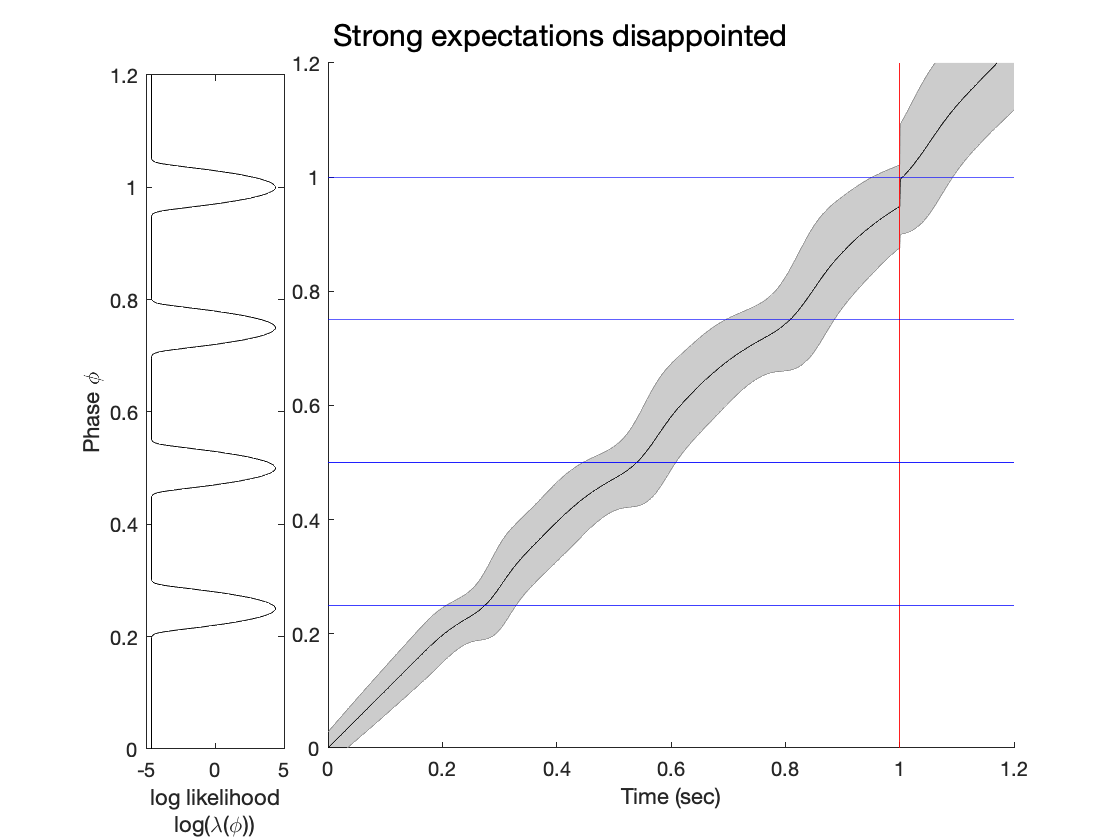


params2 = PIPPET_params(...
    'lambda_unit', 100*0.02,...
    'event_times',[1],...
    'title', 'Strong expectations disappointed');

[mu_list, C_list] = run_PIPPET(params2);

## Swingin'

The filter detects and adjusts to a phase shift in a swung rhythm.

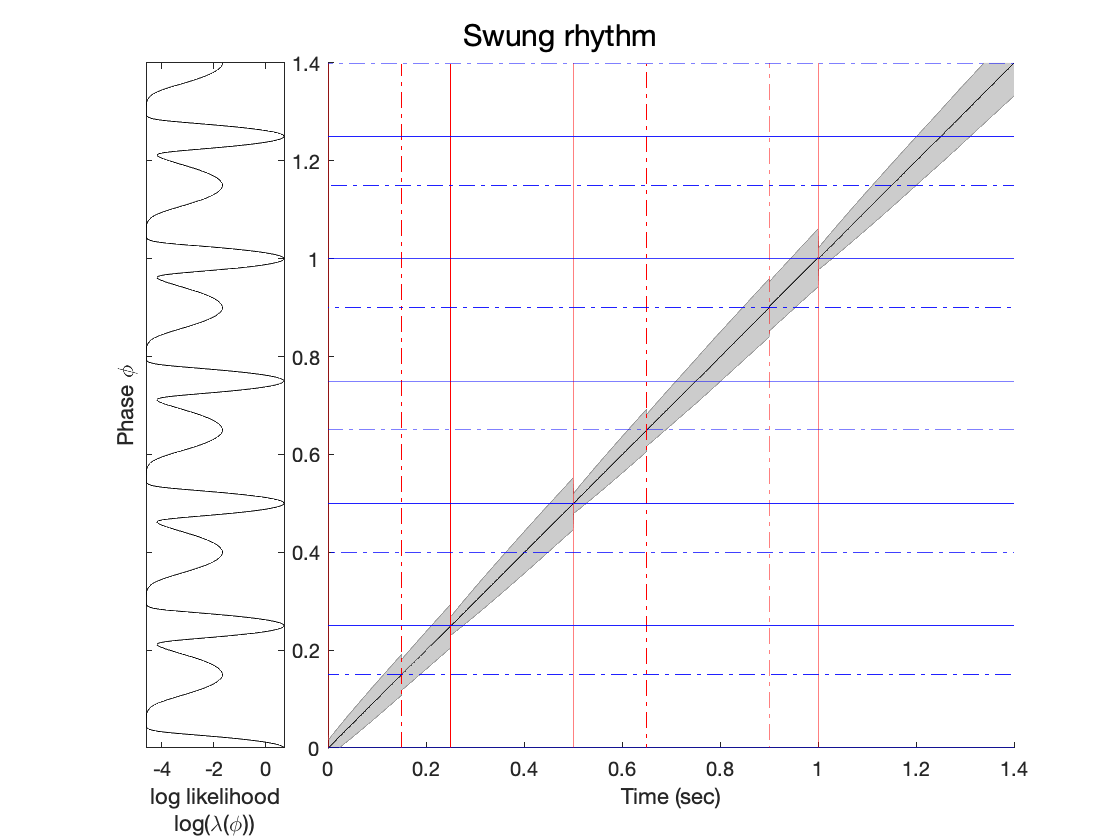

event_times = [0, 0.150, 0.2500, 0.5000, 0.650, 0.900, 1.0000];
highlight_event_indices = [1,0,1,1,0,0,1];
highlight_expectations = [1,0];

params = PIPPET_params(...
    'events_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times,...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Swung rhythm', ...
    'tmax', 1.4);

[mu_list, C_list] = run_PIPPET(params);

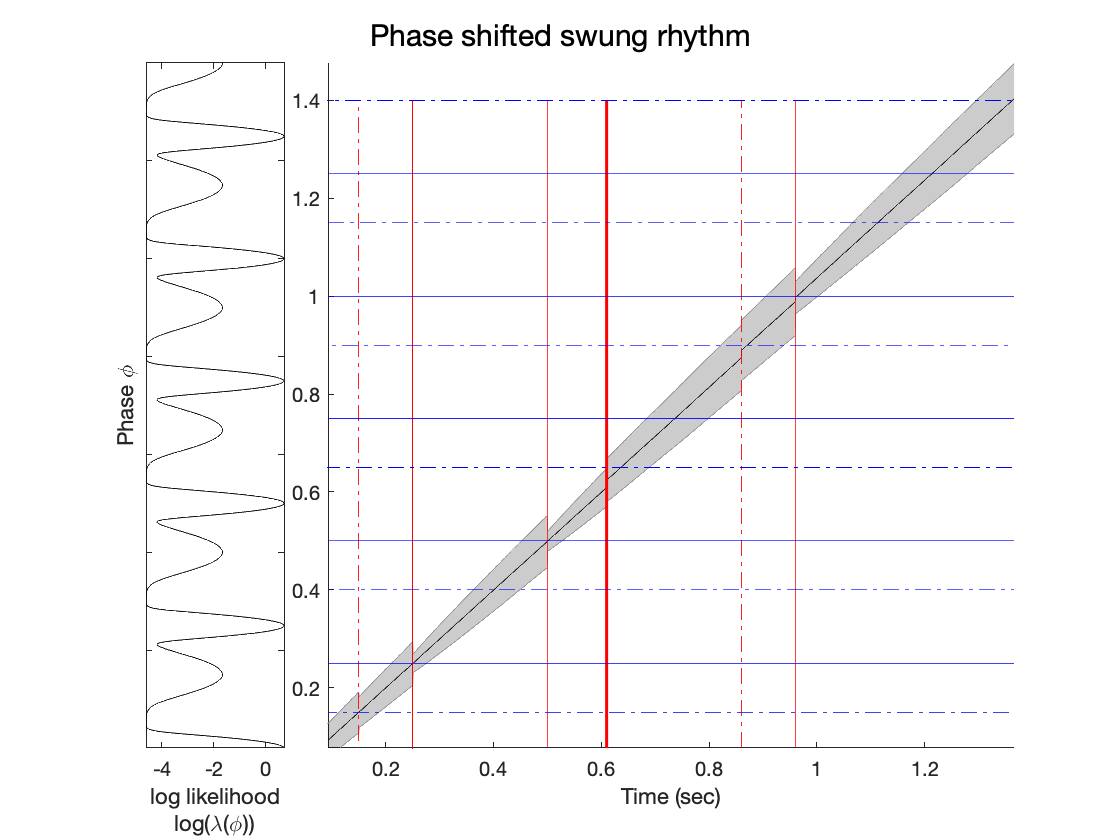


event_times(5:end)=event_times(5:end)-.04;

highlight_event_indices = [1,0,1,1,2,0,1];

params = PIPPET_params(...
    'events_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times,...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Phase shifted swung rhythm', ...
    'tmax', 1.4);

[mu_list, C_list] = run_PIPPET(params);

## Confused

If expected timing of subdivisions is not sufficiently precise, swung and syncopated rhythms can be confusing!

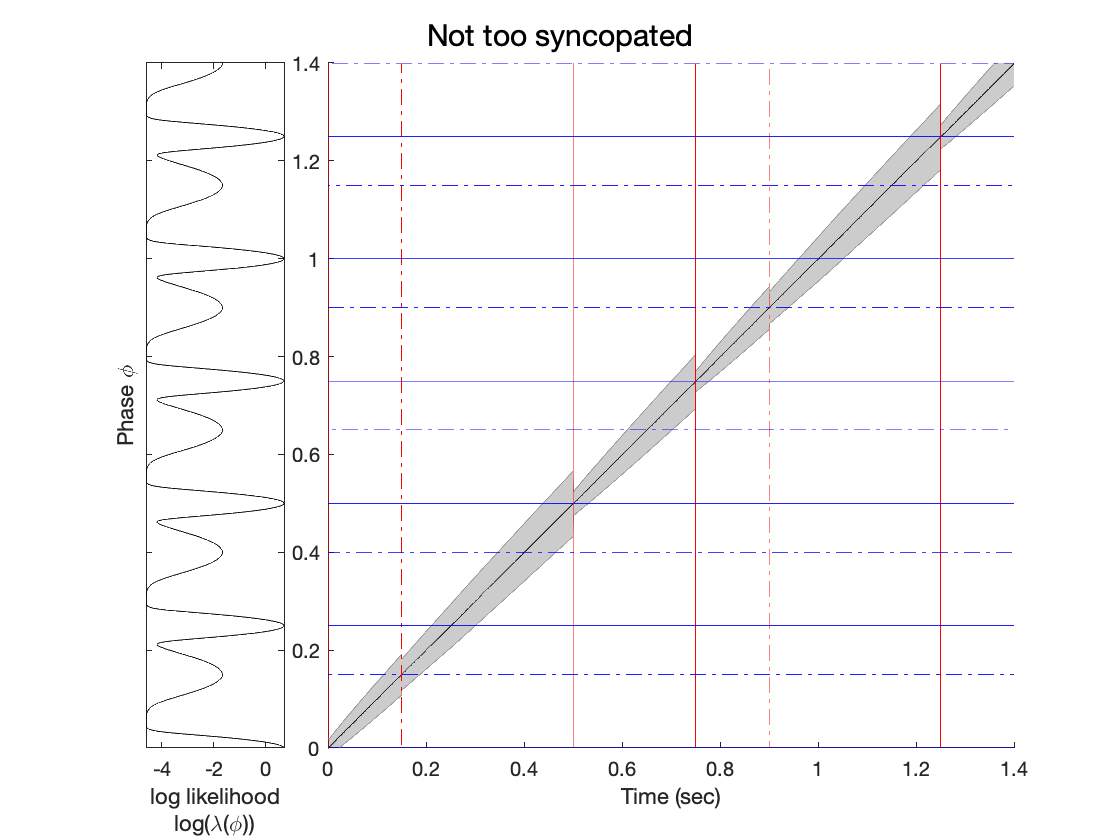

event_times = [0, 0.150, .5, .75, .9, 1.25];
highlight_event_indices = [1,0,1,1,0,1];
highlight_expectations = [1,0];

params = PIPPET_params(...
    'events_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times,...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Not too syncopated','tmax', 1.4);
[mu_list, C_list] = run_PIPPET(params);

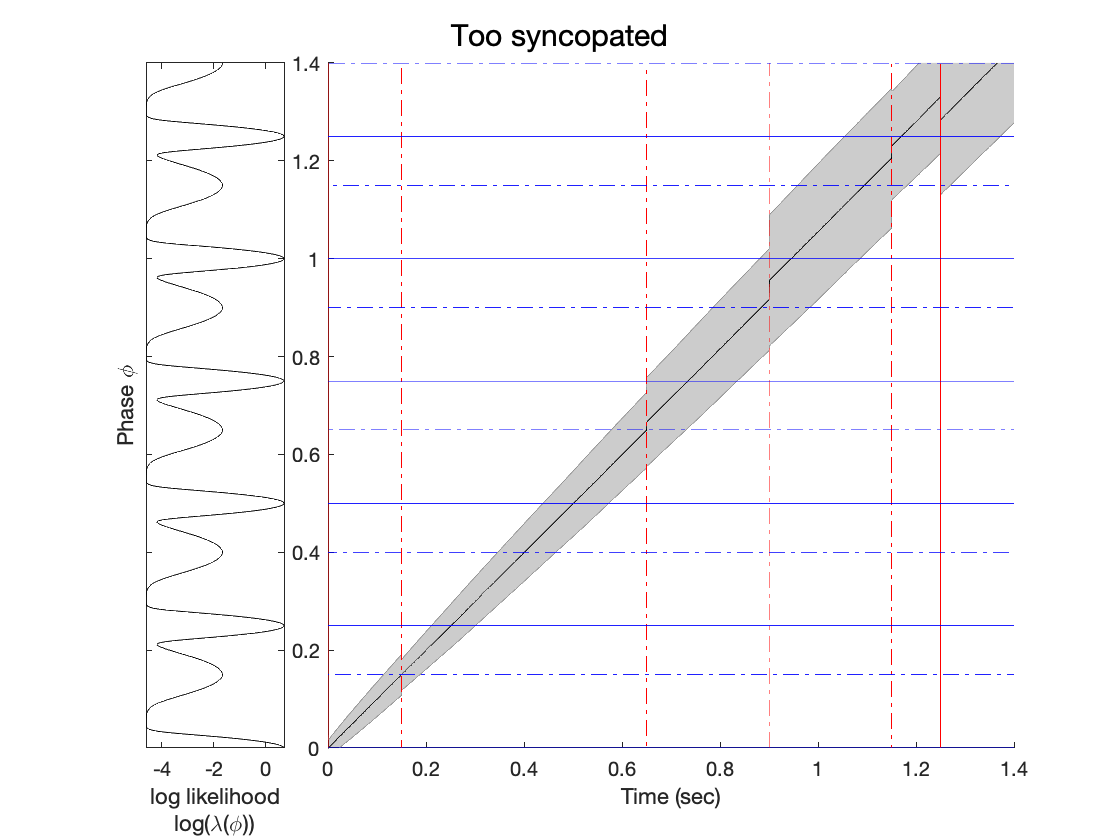


event_times = [0, 0.150, .65, .9, 1.15, 1.25];
highlight_event_indices = [1,0,0,0,0,1];

params = PIPPET_params(...
    'events_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Too syncopated','tmax', 1.4);

[mu_list, C_list] = run_PIPPET(params);

## In seven

The filter detects and adjusts to a phase shift in a 7/8 groove.

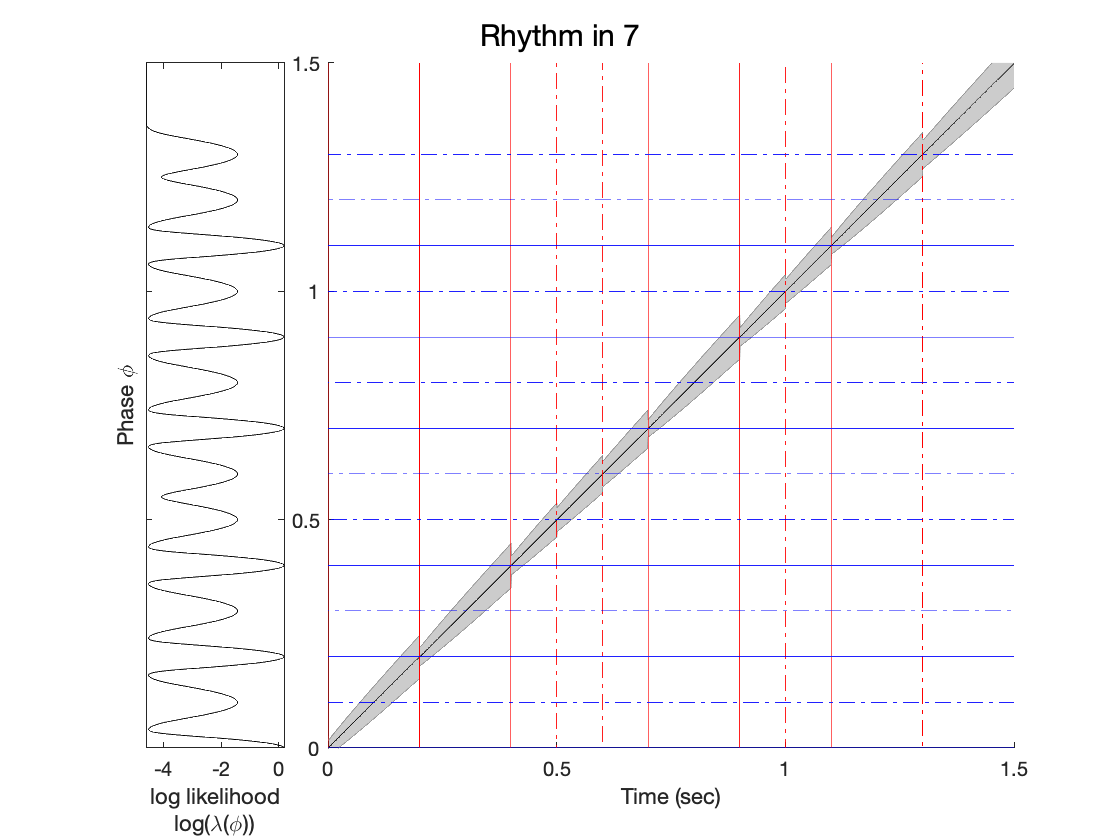


event_times = [0, .2, .4, .5, .6, .7, .9, 1, 1.1, 1.3];
highlight_event_indices = [1, 1, 1, 0, 0, 1, 1, 0, 1, 0];
highlight_expectations = [1,0,1,0,1,0,0];
params = PIPPET_params(...
    'events_unit', 0:.1:.6,...
    'variance_unit', [.0001, .0003, .0001, .0003, .0001, .0003, .0003],...
    'lambda_unit', [.03, .01,.03, .01,.03, .01,.01],...
    'expected_cycles', 2,...
    'expected_period', .7,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Rhythm in 7', ...
    'tmax', 1.5);
[mu_list, C_list] = run_PIPPET(params);

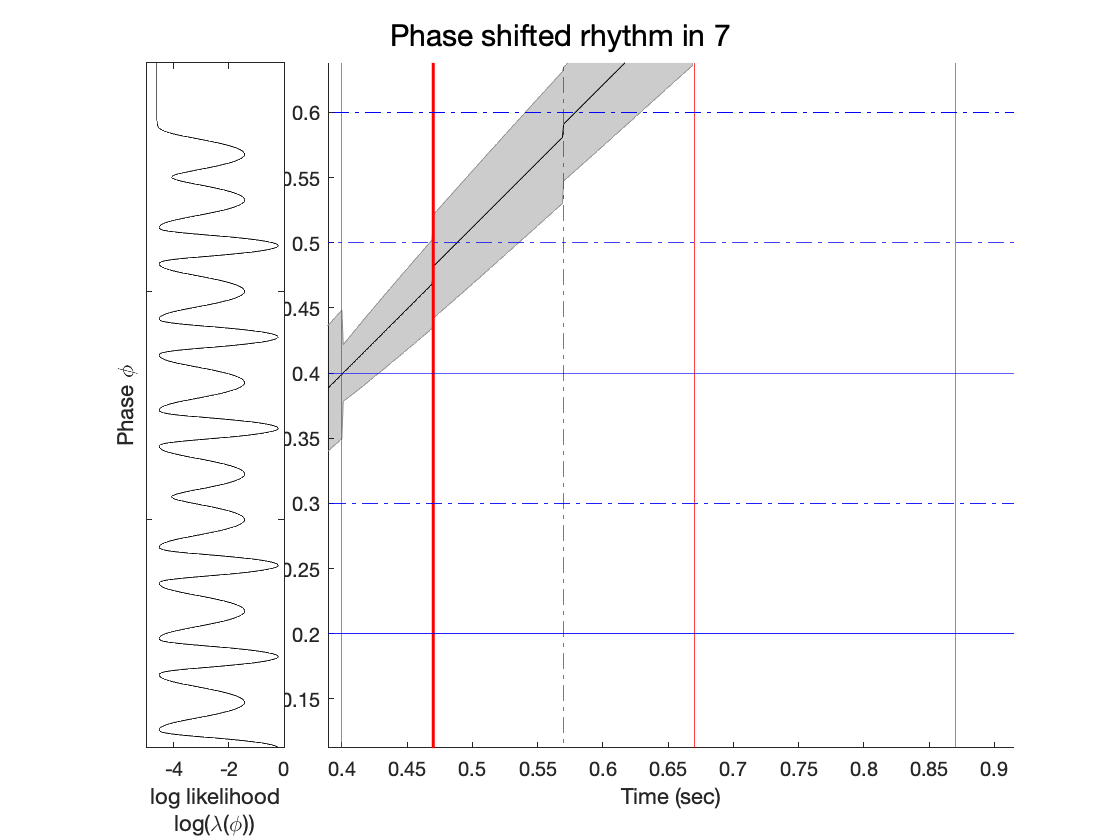



event_times(4:end)=event_times(4:end)-.03;
highlight_event_indices(4) = 2;

params = PIPPET_params(...
    'events_unit', 0:.1:.6,...
    'variance_unit', [.0001, .0003, .0001, .0003, .0001, .0003, .0003],...
    'lambda_unit', [.02, .01,.02, .01,.02, .01,.01],...
    'expected_cycles', 2,...
    'expected_period', .7,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Phase shifted rhythm in 7', ...
    'tmax', 1.5);
[mu_list, C_list] = run_PIPPET(params);

## Drum track expectations

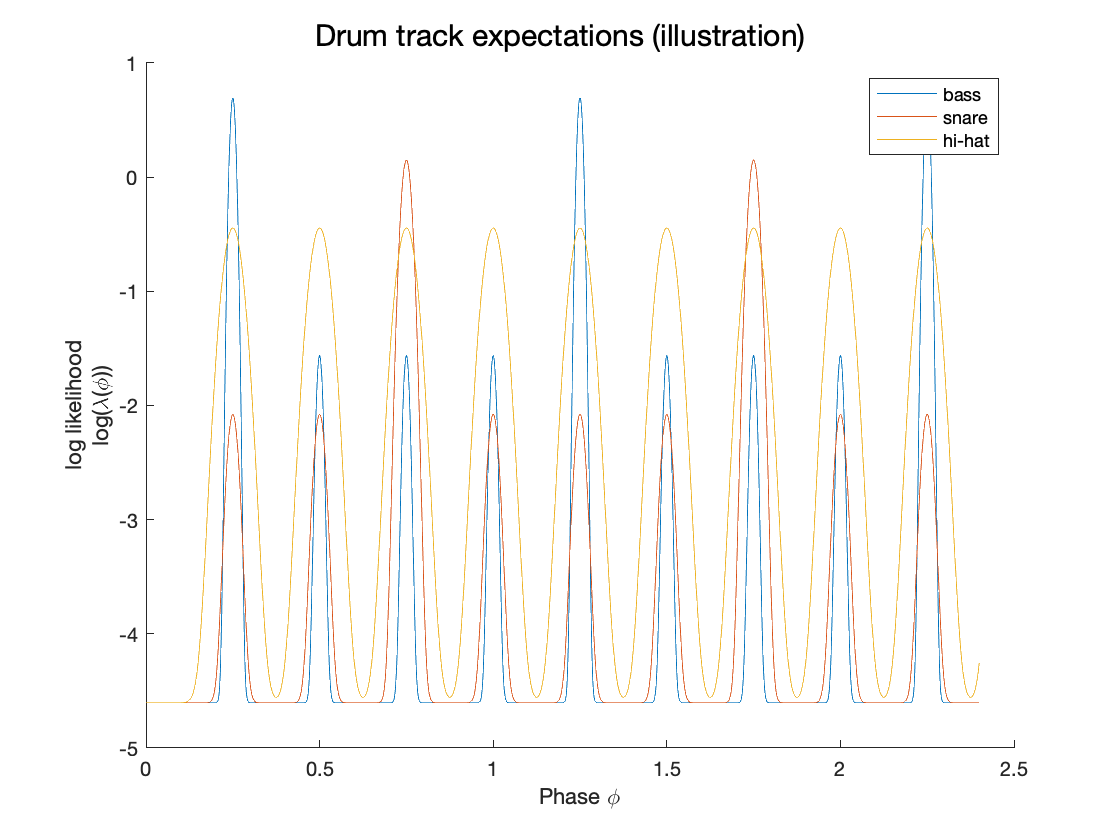

bass_variance = 0.0001*[1,1,1,1];
snare_variance = 0.0003*[1,1,1,1];
hihat_variance = 0.001*[1,1,1,1];

bass_lambda = [.05, .005, .005, .005];
snare_lambda = [.005, .005, .05, .005];
hihat_lambda = [.05, .05, .05, .05];

means = [.25, .5, .75, 1];

params = PIPPET_params(...
    'n_streams', 3,...
    'events_unit', {means, means, means},...
    'variance_unit', {bass_variance, snare_variance, hihat_variance},...
    'lambda_unit', {bass_lambda, snare_lambda, hihat_lambda},...
    'lambda_0', {.01, .01, .01},...
    'expected_cycles', 3,...
    'expected_period', 1,...
    'event_times', {[],[],[]},...
    'title', 'Drum track');

xlist = 0:.001:2.4;
figure()
hold on;
plot(xlist, log(params.streams{1}.expect_func(xlist)))
plot(xlist, log(params.streams{2}.expect_func(xlist)))
plot(xlist, log(params.streams{3}.expect_func(xlist)))
legend('bass', 'snare', 'hi-hat')
xlabel('Phase \phi')
ylabel({'log likelihood';'log(\lambda(\phi))'});
sgtitle('Drum track expectations (illustration)')

## Basic expectations

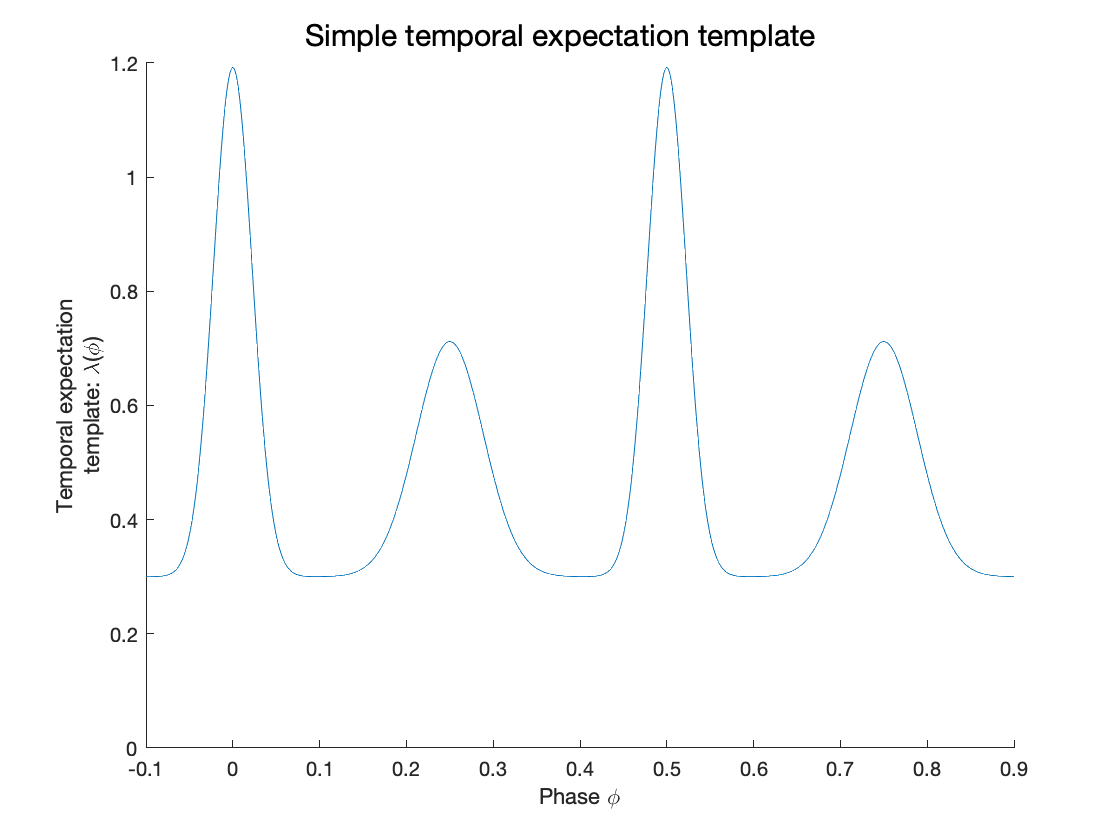

bass_variance = 0.0005*[1,3,1,3];

bass_lambda = [.05, .04, .05, .04];

means = [0, .25, .5, .75];

params = PIPPET_params(...
    'n_streams', 1,...
    'events_unit', {means},...
    'variance_unit', {bass_variance},...
    'lambda_unit', {bass_lambda},...
    'lambda_0', {.3},...
    'expected_cycles', 3,...
    'expected_period', 1,...
    'event_times', {[],[],[]},...
    'title', 'Drum track');

xlist = -.1:.001:.9;
figure()
hold on;
plot(xlist, params.streams{1}.expect_func(xlist))
ylim([0, 1.2])
xlim([-.1, .9])
%legend('bass')
xlabel('Phase \phi')
ylabel({'Temporal expectation';'template: \lambda(\phi)'});
sgtitle('Simple temporal expectation template')